### **PBC Calculation**

clear variables
close all
clc

First of all we define the physical parameters of our system:

particleDensity = 1 % n = N\L

particleDensity = 1

cutoff = 55 % In ``Hartree''

cutoff = 55

V0 = 20 % In ``Hartree''

V0 = 20

W = 0.2 % Width of V(x)

W = 0.2000

a = 1; % Lattice Parameter

And some computational parameter:

step = 100;     % Accuracy of numerical integrals
dx   = 1/step;
basisDIM = 700; % Basis dimension

Thermodynamic Limit:

$L\to\infty$, $N\to\infty$ such that $N/L = n$ is constant. 

So we need a cycle over L values:

Lmin = 162;  %
Lmax = 162;  % Only even values <=> Spinless electrons
Lstep = 20;  %

poles = zeros(step,step,step);
residues = zeros(step,step,step);

for L = Lmin:Lstep:Lmax 
    
    N = particleDensity*L;

Then we build the crystal hamiltonian computing matrix elements$\{\langle \psi^0_n | K + V(x) | \psi^0_m\rangle\}$:    

    % BZ k-points:
    
    N_b = nearest( basisDIM / L ) % Number of Bands
    E_k = zeros(N_b, L);
    c_k = zeros(N_b,N_b, L);

    dk = 2*pi/L;
    for k = dk:dk:2*pi
        ik = nearest(k/dk);
        % Hamiltonian Matrix for the u_k (psi_k actually?)
        H_k = zeros(N_b,N_b);
        for n = (-N_b/2 + 1):(N_b/2)
            for m = (-N_b/2 + 1):(N_b/2)
                if n == m
                %% Kinetic (diagonal) part %%
                H_k(n + N_b/2,n + N_b/2) = 1/2*(q(ik,L)+G(n-1,1))^2;
                %H_k(n + N_b/2,n + N_b/2) = 1/2*(G(n-1,1))^2 - 1j*(G(n-1,1))*q(ik,L)+ 1/2*q(ik,L)^2;
                end    
                %% Periodic potential part 
                integrand = @(x) exp(1i*(G(n-1,1)-G(m-1,1))*x).*V(x,L,V0,W);
                braket = 1/L * integral(integrand,0,L);
                H_k(n + N_b/2,m + N_b/2) = H_k(n + N_b/2,m + N_b/2) + braket;
            end
        end

And look for eigen values and vectors:

        [c_k(:,:,ik), E_k(:,ik)] = eig(H_k,'vector');
    end

So now we compute the Fermi Energy of the perturbed system:

    if mod(particleDensity,2) ~= 0 % Metal
        Eval = sort(E_k(nearest(particleDensity/2),:));
        nF = N/2;
        EF = Eval(nF);
    else % Insulator
        Eval = E_k(nearest(particleDensity/2),:);
        Econd = E_k(nearest(particleDensity/2)+1,:);
        EF = mean([max(Eval), min(Econd)]);
        nF = -1; % undefined...
    end

Resulting energy scheme is:

    if L == Lmax
    numBands = 3; % How much bands to display
    for k = dk:dk:2*pi
        ik = nearest(k/dk);
        scatter(k-pi*ones(1,numBands),E_k(1:numBands,ik),'markeredgecolor','black','markerfacecolor',[0, 0.4470, 0.7410]); hold on
    end
    xlim([-pi,pi])
    ylim([5,53])
    yline(EF,'--','color', 'red','LineWidth', 1.5);
    ylabel('Atomic Units')
    title(sprintf('PBC Energy Levels for N = %d',N));
    set(gca, 'Box', 'on');
    set(gca,'xtick',[-pi,0,pi]);
    xticklabels({'-\pi/a','\Gamma','\pi/a'})
    end

## Geometrical Drude Weight

$D = 2v_\mathrm{F}$, with some care on what $v_\mathrm{F}$ is:

    if nF > 2
     % PBC Fermi velocity
        vF = (Eval(nF+2)-Eval(nF-2))/(2*dk);
     % PBC Geometrical Drude Weight
        deltaL = L-Lmin;
        Dw(deltaL/Lstep + 1) = 2*vF/pi; % Metal
    else
        deltaL = L-Lmin;
        Dw(deltaL/Lstep + 1) = 0;       % Insulator
    end

## Kubo Poles and Residues

Now we proced with linear response evaluation (Kubo Formulae)

- First we build up wavefunctions:

    x = linspace(0,L,step*L);
    psi_k = cell(1,L);
    for ik = 1:L
     psi_k{ik} = zeros(length(x),N_b);
        for n = 1:N_b
          psi_x = zeros(1,length(x));
          for m = 1:N_b
              psi_x = psi_x + psi0(x,m-1,L) .* c_k(m,n,ik);% .* exp(1j.*ik.*dk.*x);
          end
          psi_k{ik}(:,n) = psi_x;
        end
%         if L == Lmax
%         figure("Name",'Crystal Wavefunctions')
%         plot(x,V(x,L,V0,W),'color',[0.7,0.7,0.7],'linewidth',1.5); hold on
%             for n = 1:N_b
%                 plot(x,V0*real(psi_k{ik}(:,n)), 'linewidth', 1.5);
%             end
%         end        
    end

- Then we apply the velocity operator $\hat{v} = i  \frac{\mathrm{d}}{\mathrm{d}x}$:

     vpsi_k = cell(1,L);
     dpsi_dx = zeros(1,length(x));
     for ik = 1:L
         vpsi_k{ik} = zeros(length(x),N_b);
         for n = 1:N_b
             dpsi_dx(1:(length(x)-1)) = diff(psi_k{ik}(:,n))/dx;
             dpsi_dx(length(x)) = dpsi_dx(length(x)-1); % Border Trick
             vpsi_k{ik}(:,n) = 1j * dpsi_dx;
         end
%          if L == Lmax
%              figure("Name",'Derivative of Crystal Wavefunctions')
%              for n = 1:N_b
%                   plot(x,imag(vpsi_k{ik}(:,n)), 'linewidth', 1.5); hold on
%              end
%          end
     end

- So we can compute pole frequencies and residues:

     % Journey through all possible excited (many-body) states compatible with Pauli principle
     w = zeros(N_b,L);
     res = zeros(N_b,L);
     swm = zeros(N_b,L);
     for ik = 1:L
         n = nearest(particleDensity/2); % Valence Band
         if E_k(n,ik) <= EF % We want just the ground state!
             for m = (n+1):N_b % Excited States
                     dw = E_k(m,ik) - E_k(n,ik);
                     if dw < cutoff
                     w(m-n,ik) = dw; % Pole frequency
                     braket_nm = conj(psi_k{ik}(:,n)).*vpsi_k{ik}(:,m);
%                               if L == Lmax
%                                   figure("Name",'Relevant Overlap')
%                                   plot(x,real(braket_nm), 'linewidth', 1.5); hold on
%                                   plot(x,imag(braket_nm), 'linewidth', 1.5);
%                               end
                     braket_mn = conj(vpsi_k{ik}(:,m)).*psi_k{ik}(:,n);
                     M1 = sum(braket_nm)*dx;
                     M2 = sum(braket_mn)*dx;
                     if abs(M1) < 0.001 || abs(M2) < 0.001
                      res(m-n,ik) = 0;
                      swm(m-n,ik) = 0;
                     else
                      res(m-n,ik) = 4*M1*M2/(dw*L); 
                      swm(m-n,ik) = 4*M1*M2/(dw*dw*L); 
                     end
                     end
             end  
        end
     end
     

Closing L cycle

N_b = 4

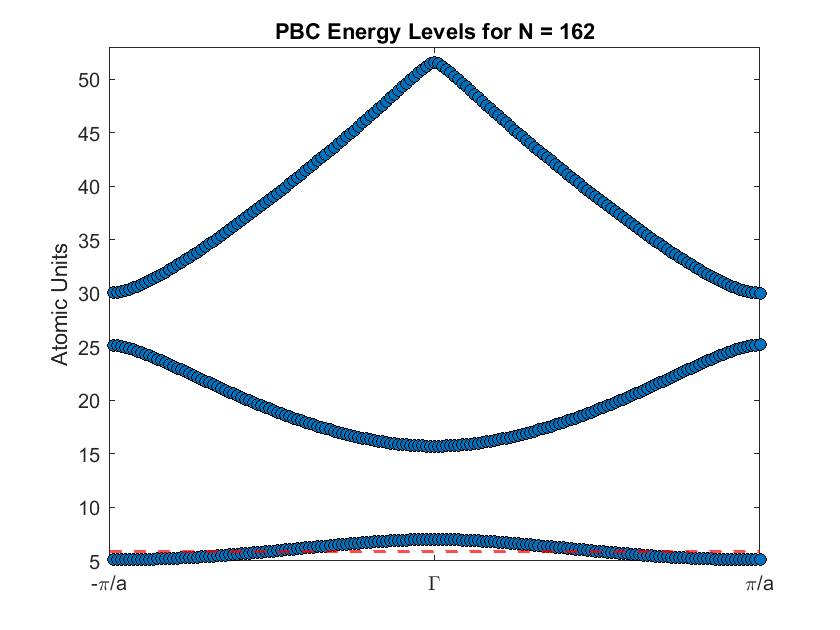

SumRes(deltaL/Lstep + 1) = sum(sum(res));
SWM(deltaL/Lstep + 1) = sum(sum(swm));
end

F-sum and SWM-sum:

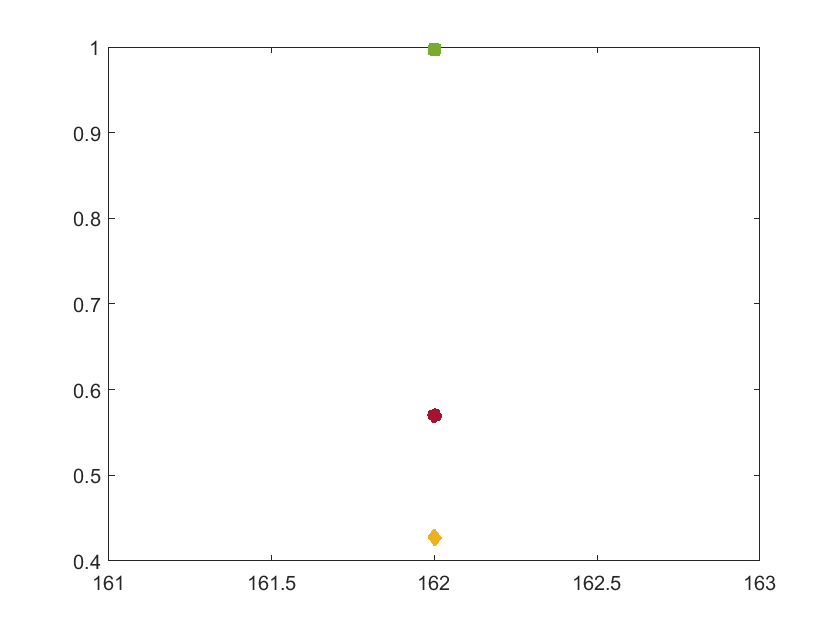

% R-sum
Ls = Lmin:Lstep:Lmax;

for L = Ls
    deltaL = L-Lmin;
    Rsum(deltaL/Lstep+1) = SumRes(deltaL/Lstep+1);
end
% F-sum
Fsum = Rsum + Dw;
% Flow of sums
blood = [0.6350, 0.0780, 0.1840];
green = [0.4660, 0.6740, 0.1880];
orange = [0.9290, 0.6940, 0.1250];
figure("Name",'F-Sum Analysis')
plot(Ls,Fsum,'s-','color',green,'LineWidth',1.5,'MarkerFaceColor',green);hold on
plot(Ls,Rsum,'d-','color',orange,'LineWidth',1.5,'MarkerFaceColor',orange);
plot(Ls,Dw,'o-','color',blood,'LineWidth',1.5,'MarkerFaceColor',blood);

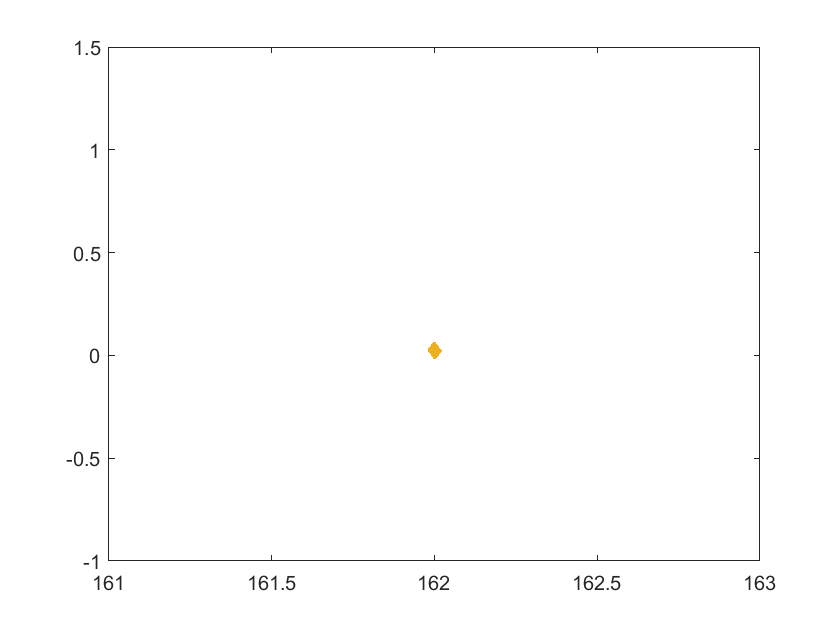

% SWM-sum
Ls = Lmin:Lstep:Lmax;
figure("Name",'SWM within PBCs')
plot(Ls,SWM,'d-','color',orange,'LineWidth',1.5,'MarkerFaceColor',orange);

Conductivity

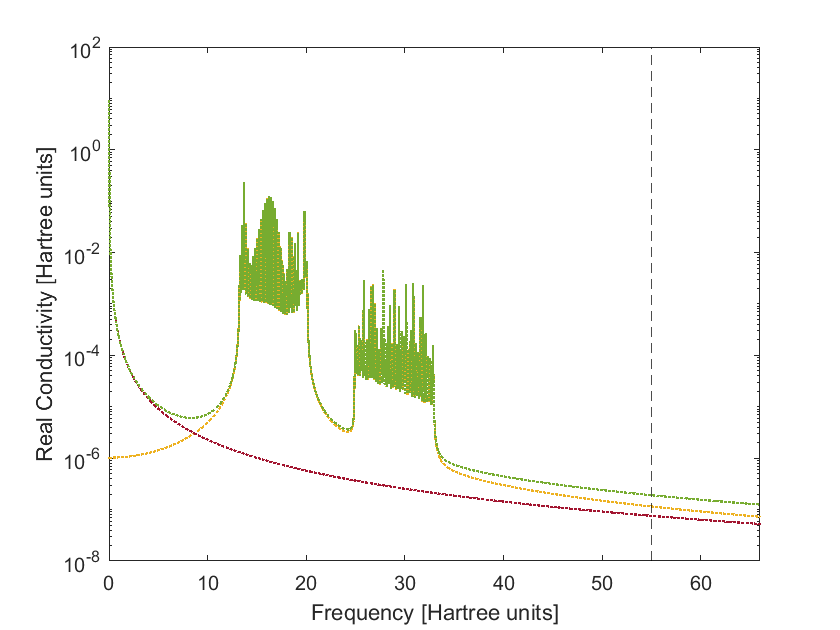

figure("Name", 'PBC Conductivity')
z = linspace(0,1.2*cutoff,step*10);
Gz = zeros(1,length(z));
eta = 0.005; %3*EF/Lmax;
freqs = w(w~=0);
resds = res(res~=0);
minRes = min(resds(resds~=0));
maxRes = max(resds(resds~=0));
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        Gz = Gz + 1i*Res.*(1./(dw.*(z-dw+1i*eta))+1./(dw.*(z+dw+1i*eta)));
end
Dz = 1i*max(Dw).*(1./(dw.*(z+1i*eta))+1./(dw.*(z+1i*eta)));
plot(z,real(Gz),':','LineWidth', 1, 'color', orange); hold on
plot(z,real(Dz),':','LineWidth', 1, 'color', blood); 
plot(z,real(Dz+Gz),':','LineWidth', 1, 'color', green); 
maxCond = unique(max(real(Dz)));
minCond = unique(min(real(Gz)));
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
%set(gca,'Ylim',[minCond,maxCond]);
set(gca,'Yscale','log')
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')

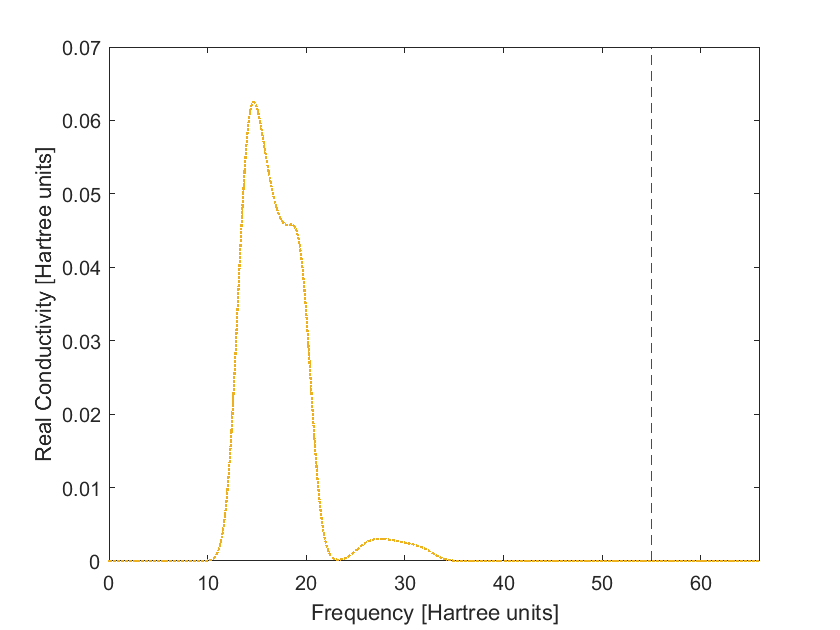


figure("Name", 'PBC Conductivity [GAUSSIAN SMEARING]')
z = linspace(0,1.2*cutoff,step*10);
Gz = zeros(1,length(z));
sigma = 1; %3*EF/Lmax;
freqs = w(w~=0);
resds = res(res~=0);
minRes = min(resds(resds~=0));
maxRes = max(resds(resds~=0));
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        Gz = Gz + 1/(sigma*sqrt(2*pi)).*Res.*exp(-0.5.*(z-dw/sigma).^2);
end
Dz = 1/(sigma*sqrt(2*pi)).*max(Dw).*exp(-0.5.*(z/sigma).^2);
plot(z,real(Gz),':','LineWidth', 1, 'color', orange); hold on
%plot(z,real(Dz),':','LineWidth', 1, 'color', blood); 
%plot(z,real(Dz+Gz),':','LineWidth', 1, 'color', green); 
maxCond = unique(max(real(Dz)));
minCond = unique(min(real(Gz)));
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
%set(gca,'Ylim',[minCond,maxCond]);
%set(gca,'Yscale','log')
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')

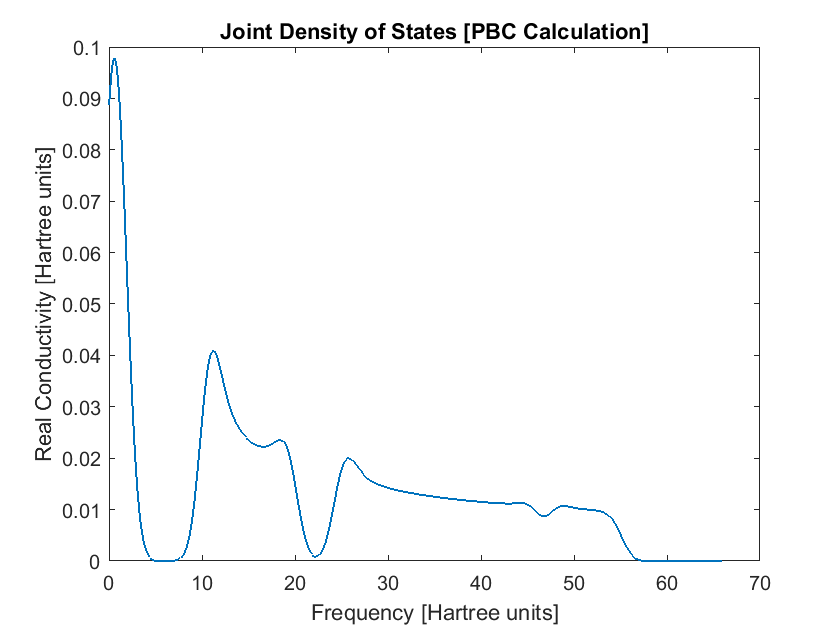


figure("Name",'Joint DOS PBC')
sigma = 1; 
z = linspace(0,1.2*cutoff,step*10);
jDOS = zeros(1,length(z));
Norm = 0;
for ik = 1:L
  for jk = 1:L
     n = nearest(particleDensity/2); % Valence Band
     if E_k(n,ik) <= EF % We want just the ground state!
         for m = n:N_b % Excited States
         dw = E_k(m,jk) - E_k(n,ik);
         if dw < cutoff
            jDOS = jDOS + 1/(sigma*sqrt(2*pi)).*exp(-0.5.*(z-dw/sigma).^2);
            Norm = Norm + 1;
         end
         end
     end
  end
end
plot(z,jDOS/Norm,'LineWidth', 1); 
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')
title('Joint Density of States [PBC Calculation]')

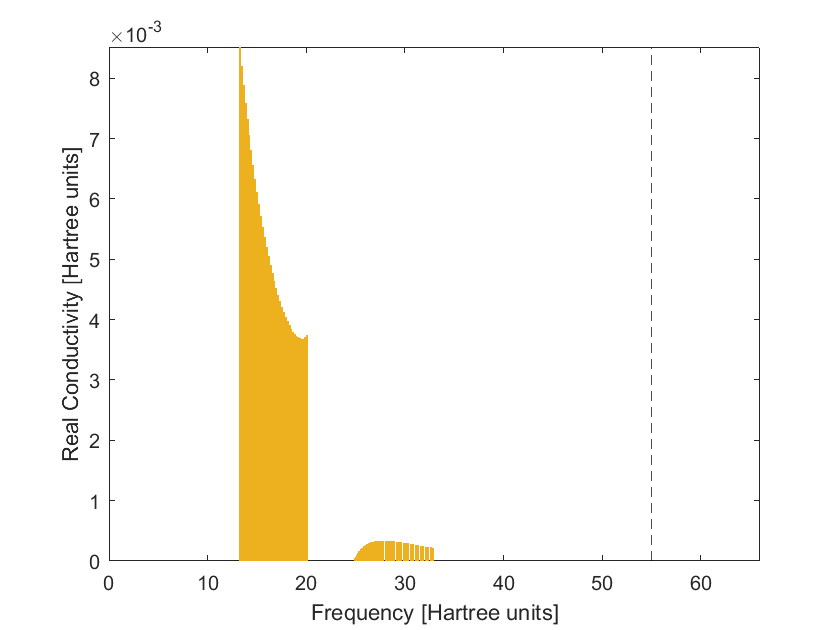


% 
% figure("Name",'Unsmeared Conductivity LOG')
% % for ik = 1:L
% %   for jk = 1:L
% %      n = nearest(particleDensity/2); % Valence Band
% %      if E_k(n,ik) <= EF % We want just the ground state!
% %          for m = n:N_b % Excited States
% %          dw = E_k(m,jk) - E_k(n,ik);
% %          if dw < cutoff
% %          plot([dw,dw],[minRes,maxRes],'-','LineWidth', 1, 'color', [0 0 0 0.1]); hold on
% %          end
% %          end
% %      end
% %   end
% % end
% for n = 1:length(freqs)
%         dw = freqs(n);
%         Res = resds(n);
%         plot([dw,dw],[minRes,Res],'-','LineWidth', 1, 'color', orange); hold on
% end
% xline(cutoff,'--','color', 'black');
% set(gca,'Xlim',[0,1.2*cutoff]);
% set(gca,'Ylim',[minRes,maxRes]);
% set(gca,'Yscale','log')
% xlabel('Frequency [Hartree units]')
% ylabel('Real Conductivity [Hartree units]')

figure("Name",'Unsmeared Conductivity LIN')
% for ik = 1:L
%   for jk = 1:L
%      n = nearest(particleDensity/2); % Valence Band
%      if E_k(n,ik) <= EF % We want just the ground state!
%          for m = n:N_b % Excited States
%          dw = E_k(m,jk) - E_k(n,ik);
%          if dw < cutoff
%          plot([dw,dw],[minRes,maxRes],'-','LineWidth', 1, 'color', [0 0 0 0.1]); hold on
%          end
%          end
%      end
%   end
% end
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        plot([dw,dw],[0,Res],'-','LineWidth', 1, 'color', orange); hold on
end
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
set(gca,'Ylim',[0,maxRes]);
xlabel('Frequency [Hartree units]')
ylabel('Real Conductivity [Hartree units]')

Reciprocal Space wavevectors: $G = \frac{2\pi n}{a}$ 

function K = G(n,a)
         K = (2*pi*n)/a;
end

Brillouin Zone wavevectors: $k = \frac{2\pi n}{L}$

function k = q(m,L)
         k = (2*pi*m)/L;
end

Imperturbed REDUCED SCHEME eigenfunctions $\psi^0_n(x)$: 

function psi0_n = psi0(x,m,L)
         A = sqrt(1/L); % Normalization
         psi0_n = A*exp(1i*G(m,1).*x);
end

Periodic potential $V(x)$ as a sum of Gaussians:

function U = V(x,L,V0,W)
         
         U = 0;
         for x_i = 0:L+1 
             U = U + V0*exp(-(x-x_i).^2 / W^2);                        
         end
end